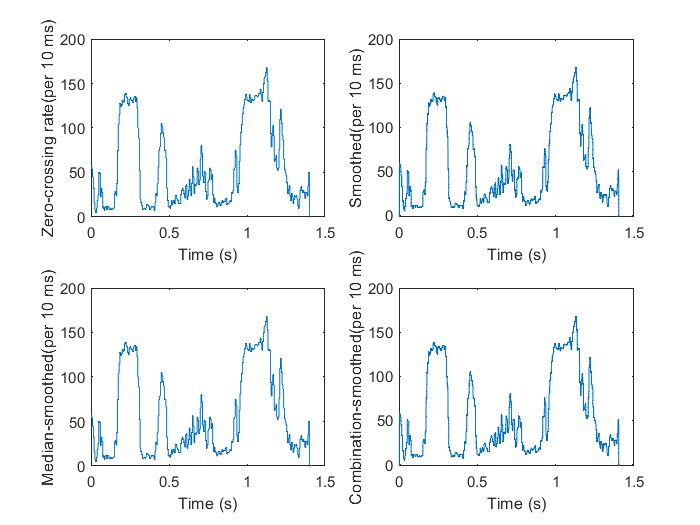

% read in speech file
[x, Fs] = audioread('test_16k.wav');

% compute short-time zero-crossing rate
frame_length = round(0.01*Fs); % 10 msec frame length
frame_shift = round(0.005*Fs); % 5 msec frame shift
zcr = zeros(1, length(x));
for i = 1:frame_shift:length(x)-frame_length
    frame = x(i:i+frame_length-1);
    zcr(i:i+frame_shift-1) = sum(abs(diff(frame>0))) / frame_length * Fs / frame_shift;
end

% plot short-time zero-crossing rate
t = (0:length(zcr)-1) / Fs;
figure;
subplot(2,2,1);
plot(t, zcr);
xlabel('Time (s)');
ylabel('Zero-crossing rate(per 10 ms)');

% design lowpass filter to preserve low frequency band
F = Fs/2;
f1 = 0.1*F; % preserve up to 1.6 kHz
f2 = 0.2*F; % remove from 3.2 kHz to 8 kHz
L = 41; % filter length
h1 = fir1(L-1, f1/F);
h2 = fir1(L-1, [f2/F, 0.5], 'STOP');
h = conv(h1, h2);

% apply lowpass filter to smooth zero-crossing rate contour
zcr_smooth = filter(h, 1, zcr);

% plot smoothed zero-crossing rate contour
subplot(2,2,2);
plot(t, zcr_smooth);
xlabel('Time (s)');
ylabel('Smoothed(per 10 ms)');

% median-smooth original zero-crossing rate contour
zcr_median = medfilt1(zcr, 7);
zcr_median = medfilt1(zcr_median, 5);

% plot median-smoothed zero-crossing rate contour
subplot(2,2,3);
plot(t, zcr_median);
xlabel('Time (s)');
ylabel('Median-smoothed(per 10 ms)');

% apply combination smoother to zero-crossing rate contour
zcr_comb = filter(ones(1,5)/5, 1, zcr_smooth);
zcr_comb = medfilt1(zcr_comb, 5);

% plot combination-smoothed zero-crossing rate contour
subplot(2,2,4);
plot(t, zcr_comb);
xlabel('Time (s)');
ylabel('Combination-smoothed(per 10 ms)');